# **電力ネットワークモデルの定義**

### **今回の演習では以下の画像に示すような「IEEE14busモデル」と呼ばれる系統モデルを解析対象にしてみます**

## **IEEE 14bus モデル**

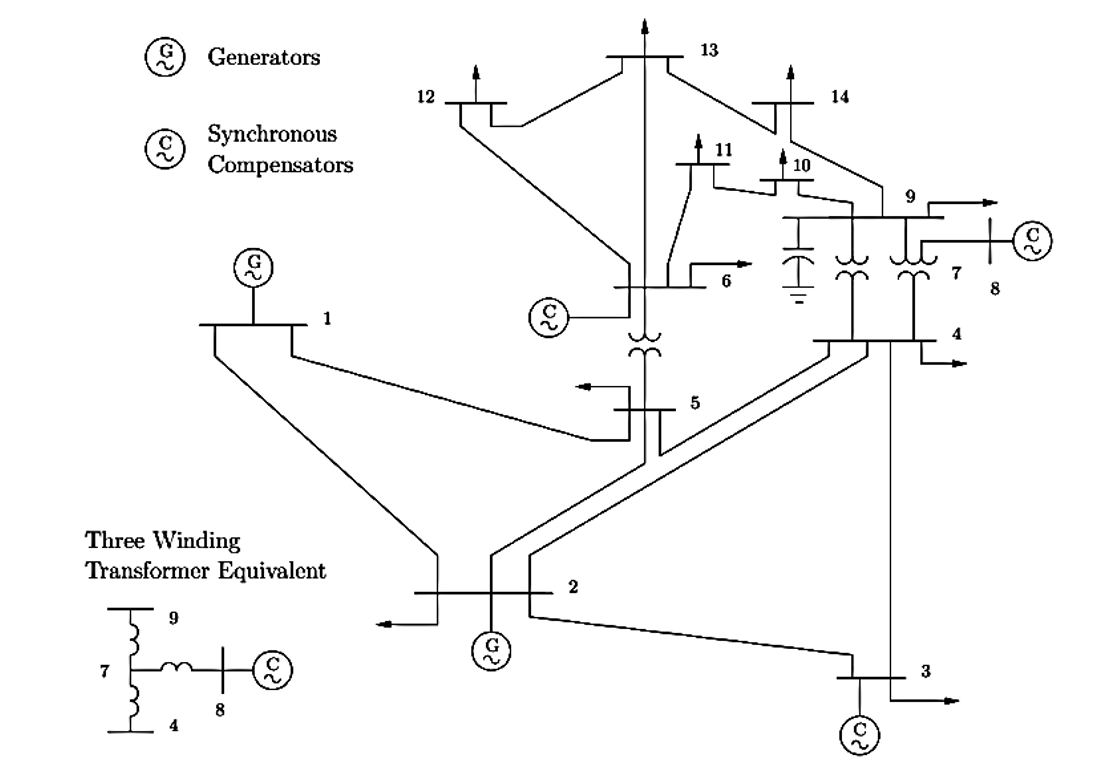

- 母線は全部で14個

- 母線1,2には同期発電機モデルが接続

- 母線3,6,8には同期調相機を接続

- 母線5-6,母線4-9,母線4-7-9の間に変圧器を接続

#### GUILDAに実装済みの標準モデルは以下のボタンから呼び出すことができます !!

net_origin = network.IEEE14bus; 

INFO: Slack bus not found. Setting the first bus 'B001' as the slack bus.
INFO: B001 set as slack bus. 
      P and Q specifications for SG1B001 ignored in powerflow calculation.


disp("IEEE14母線系統を読み込みました.")

IEEE14母線系統を読み込みました.


base_bus = net_origin.a_Bus([3,9,12,14]);
INV_past = repmat(2,[1,4]);
base_comp_name = ["LPQ2B003","LPQ1B009","LPQ1B012","LPQ1B014"];

# **系統の構成をいじってみよう !!**

## **図のように母線3,9,12,14ではGFM,GFLの選択ができるようになっています。**

## **自由に機器を選択して、系統の挙動がどのように変わるのか確認してみましょう。**

**※まずは、デフォルトの系統で実験してみることをお勧めします !!**

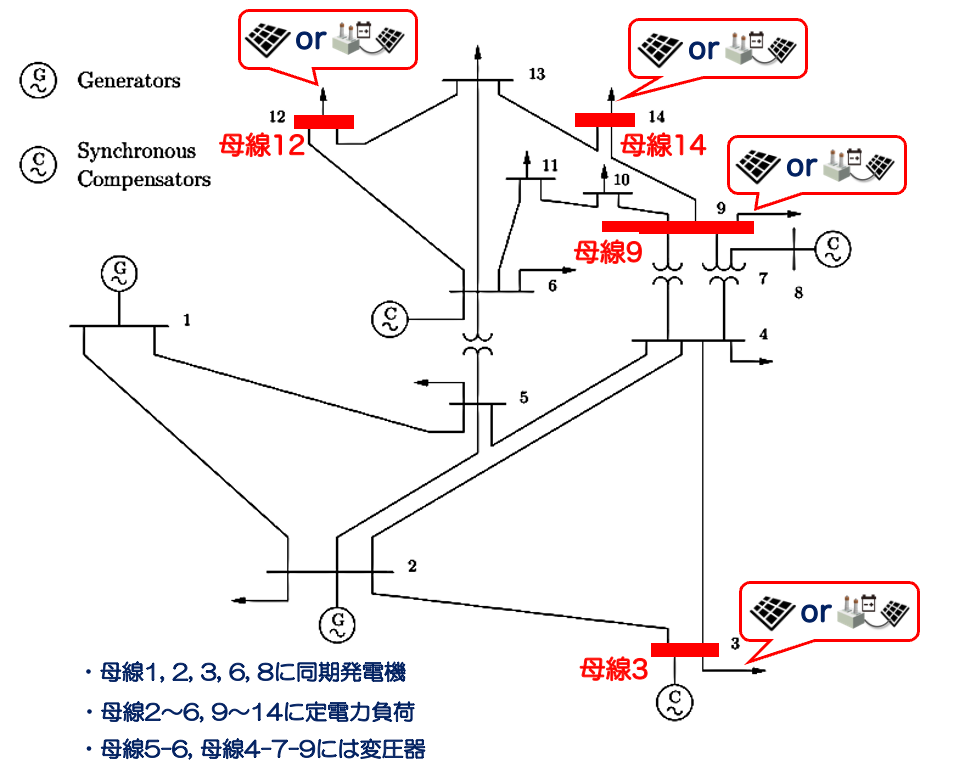

INV1 = 1;
INV2 = 2;
INV3 = 1;
INV4 = 2; 

inv_list = [INV1;INV2;INV3;INV4];

cmp_list = ["gen-classical";"load-power"];

tab_param = table(10,20,0.65,0.34, 'VariableNames', {'M','D','Xd','Xq'});
for inv = 1:numel(inv_list)
    if INV_past(inv) ~= inv_list(inv)
        % 変更する機器の名前
        base_name = base_comp_name(inv);
        % 新しく接続する機器
        new_comp  = cmp_list( inv_list(inv) );

        str_tagComp = string(base_bus{inv}.a_Component);

        % 機器を新しいものに付け替える
        base_bus{inv}.replace_component(base_name, new_comp,tab_param );    

        % 母線に接続されている機器のタグ
        l_new_tag = string(base_bus{inv}.a_Component);

        % 変更された機器のタグを取得
        comp_tag = l_new_tag(l_new_tag~=str_tagComp);
        base_comp_name(inv) = comp_tag;

        INV_past(inv) = inv_list(inv);
    end
end

net_origin.initialize;
disp("変更が反映されました。実験に移りましょう !!")

変更が反映されました。実験に移りましょう !!


# **シミュレーションの実行**

## **地絡や解列を通して系統の挙動を数値的に観察してみましょう !!**

**※ 設定によっては解けない可能性があります。その場合は設定を変えてみましょう。**

# **a) 初期値応答**

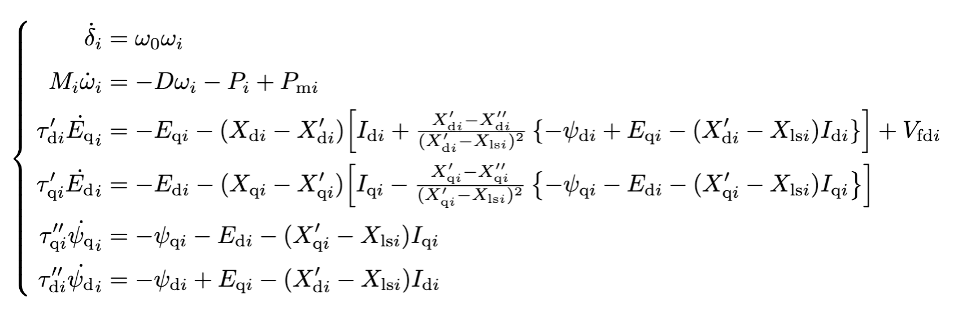

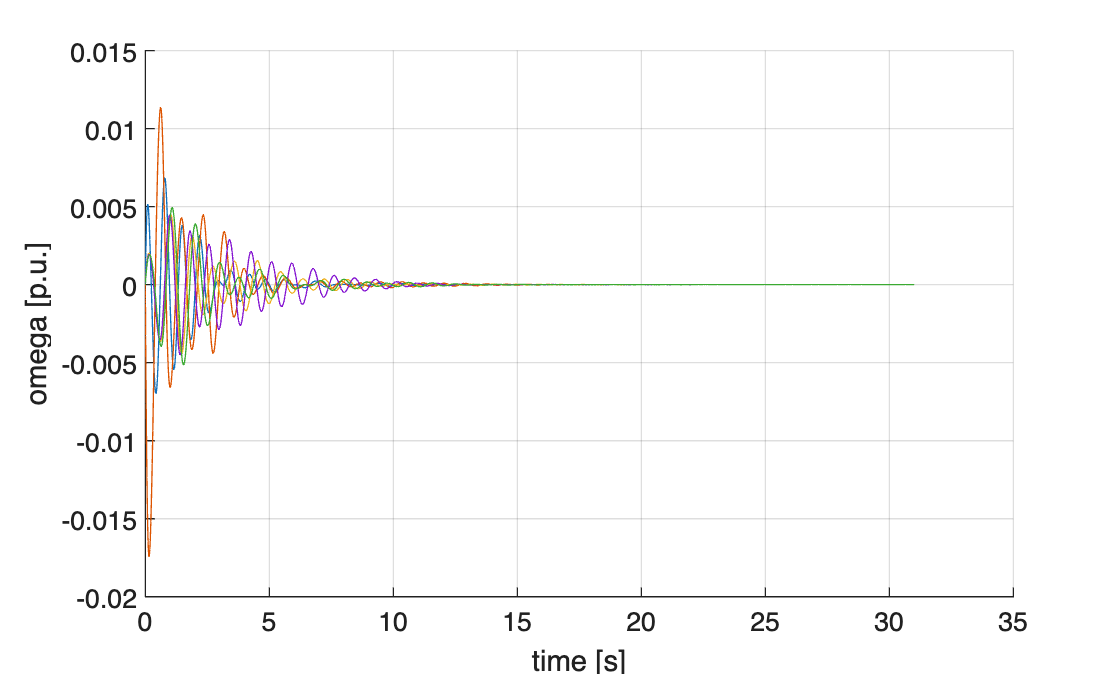

offset_bus       = 2;
offset_component = 1;
offset_state = "delta";
offset_value = 0.9;
offset_simulation_time = 31; 

COMP_offset = net_origin.a_Bus{offset_bus}.a_Component{offset_component};
strx = COMP_offset.str_x;

if offset_component > numel(net_origin.a_Bus{offset_bus}.a_Component)
    disp(" >> 母線に接続されている機器の数よりも大きなインデックスを指定しているようです。" + newline + ...
         "    母線には機器が一つ接続されているか、機器が存在しない可能性があります。" +newline + ...
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return
end

if offset_bus == 7
    disp(" >> 機器が接続されない母線を選択しているようです。" + newline + ...         
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return
end

if isempty(strx)
    disp(" >> 定電力負荷を選択しているようです。" + newline + ...
         "    定電力付加には状態変数が存在しません。"+ newline + ...
         "    上記の系統図を参考に同期発電機、もしくは同期調機を選択してみましょう !!")
    return
end

ev_offset = odeEventSet("ev_offset", net_origin, "TimeSpan", 0, "OffsetUnit", COMP_offset.str_tag, "OffsetState", offset_state, "OffsetValue", offset_value);
sol_offset = net_origin.simulate([0, offset_simulation_time], ev_offset);

xsol_offset = sol_offset.odeResults;
figure
hold on
arrayfun(@(i) plot(xsol_offset.t, xsol_offset.Bus(i).Component(1).X.omega), [1,2,3,6,8]);

grid on
xlabel("time [s]")
ylabel("omega [p.u.]")

# **b) 入力応答**

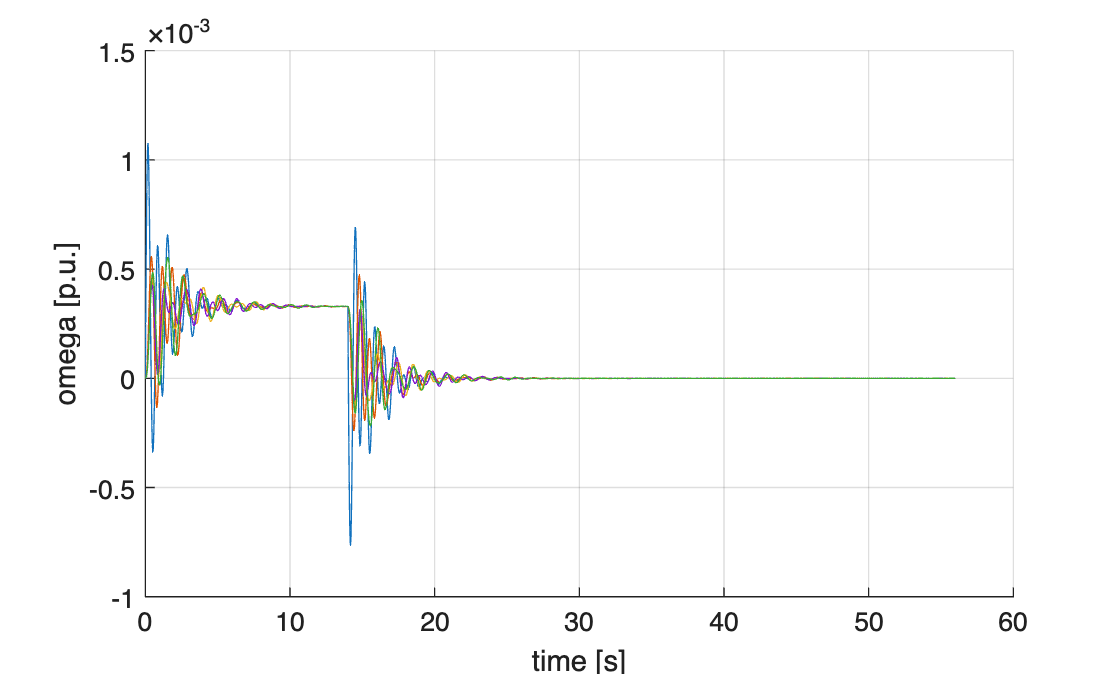

input_bus       = 1;
input_component = 1;
input_state = "Pmech";
input_value = 0.1;
input_time = 14;
input_simulation_time = 56; 


if input_component > numel(net_origin.a_Bus{input_bus}.a_Component)
    
    disp(" >> 母線に接続されている機器の数よりも大きなインデックスを指定しているようです。" + newline + ...
         "    母線には機器が一つ接続されているか、機器が存在しない可能性があります。" +newline + ...
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return    
end
COMP_input = net_origin.a_Bus{input_bus}.a_Component{input_component};
stru = COMP_input.str_u;

if input_bus == 7
    disp(" >> 機器が接続されない母線を選択しているようです。" + newline + ...         
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return
end

if isa(COMP_input, 'component.generator.abstract')
    if ~ismember(input_state, COMP_input.str_u)
        disp(" >> どうやら負荷の入力を選択しているようですね。" + newline + ...
             "    同期機への入力はタービンからの入力である Pmech と励磁機からの入力である Vfield です。" + newline + ...
             "    これら二つの内、どちらか一方を選択してみましょう !!")
        return
    end
elseif isa(COMP_input, 'component.load.abstract')
    if ~ismember(input_state, COMP_input.str_u)
        disp(" >> どうやら同期機の入力を選択しているようですね。" + newline + ...
             "    負荷への入力は有効電力である Pload と無効電力である Qload です。" + newline + ...
             "    これら二つの内、どちらか一方を選択してみましょう !!")
        return
    end
end

ev_input = odeEventSet("ev_input", net_origin, "TimeSpan", [0, input_time], "InputUnit", COMP_input.str_tag, "InputName", input_state, "InputValue", input_value);
sol_input = net_origin.simulate([0, input_simulation_time], ev_input);

xsol_input = sol_input.odeResults;
figure
hold on
arrayfun(@(i) plot(xsol_input.t, xsol_input.Bus(i).Component(1).X.omega), [1,2,3,6,8]);

grid on
xlabel("time [s]")
ylabel("omega [p.u.]")

# **c) 地絡**

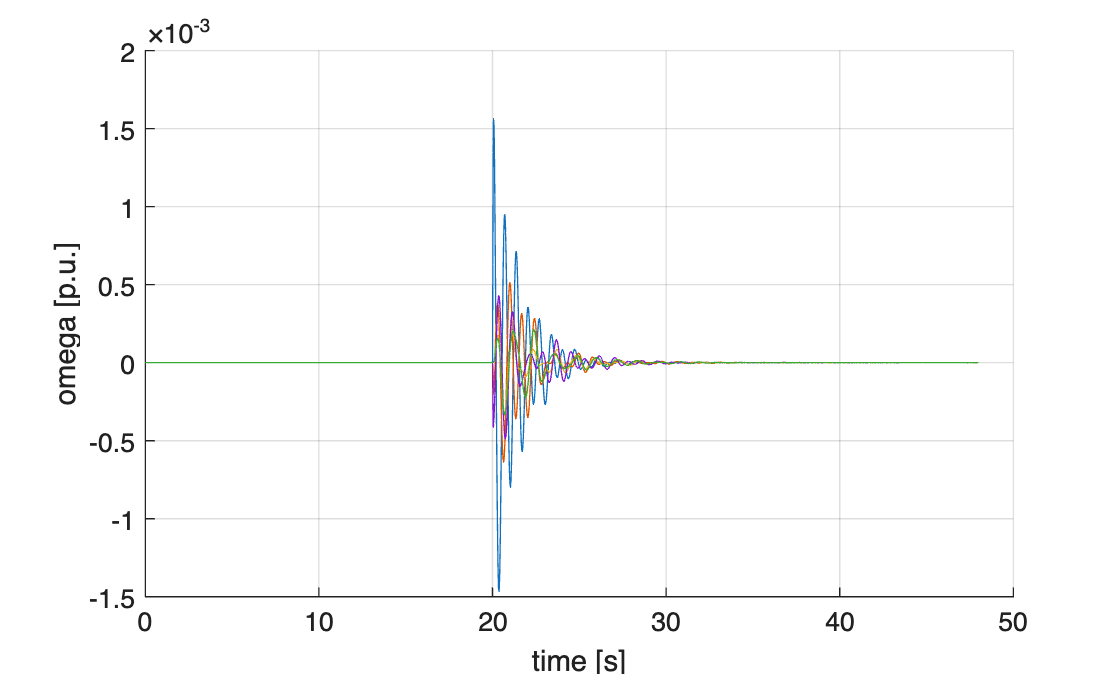

fault_bus = 8;
fault_simulation_time = 48;
fault_start_time = 20;
fault_time = 0.04; 

FBUS_tag = net_origin.a_Bus{fault_bus}.str_tag;
ev_fault = odeEventSet("ev_fault", net_origin, "TimeSpan", [fault_start_time, fault_start_time+fault_time], "FaultBus", FBUS_tag);
sol_fault = net_origin.simulate([0, fault_simulation_time], ev_fault);

xsol_fault = sol_fault.odeResults;
figure
hold on
arrayfun(@(i) plot(xsol_fault.t, xsol_fault.Bus(i).Component(1).X.omega), [1,2,3,6,8]);

grid on
xlabel("time [s]")
ylabel("omega [p.u.]")

# **d) 解列**

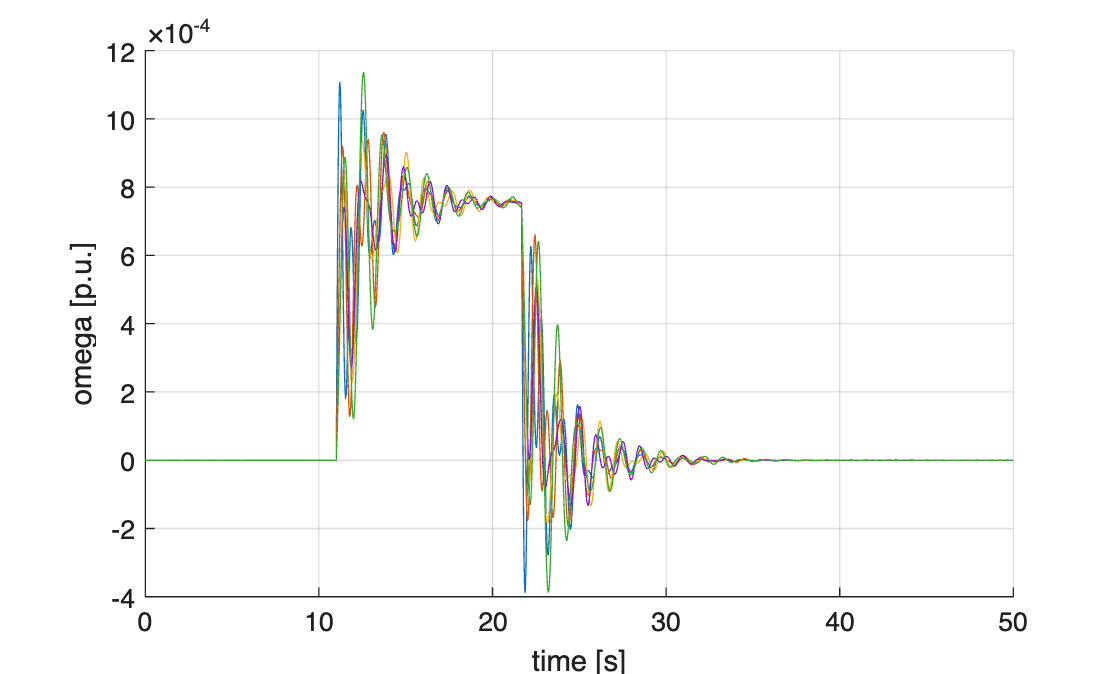

trip_bus = 2;
trip_component = 2;
trip_simulation_time = 50;
trip_start_time = 11;
trip_time = 10.67; 

TBUS = net_origin.a_Bus{trip_bus};
NumOfComp = numel(TBUS.a_Component);

if trip_component > NumOfComp
    if ~isa(net_origin.a_Bus{trip_bus}.a_Component{end}, 'component.load.abstract')
        disp(" >> 母線に接続されている機器の数よりも大きなインデックスを指定しているようです。" + newline + ...
             "    母線には機器が一つ接続されているか、機器が存在しない可能性があります。" +newline + ...
             "    上記の系統図を参考に設定を見直してみましょう !!")
        return
    end    
end

if trip_bus == 7
    disp(" >> 機器が接続されない母線を選択しているようです。" + newline + ...         
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return
end



if isscalar(net_origin.a_Bus{trip_bus}.a_Component)
    TCOMP = net_origin.a_Bus{trip_bus}.a_Component{1};
    if isa(TCOMP, 'component.generator.abstract')
        if trip_component == 2
            disp(" >> どうやら負荷を選択しているようです。" + newline + ...
                 "    この母線、実は同期機しか接続されていないんです。" + newline + ...
                 "    設定をもう一度見直してみましょう !!")
            return
        end
    elseif isa(TCOMP, 'component.load.abstract')
        if trip_component == 1
            disp(" >> どうやら同期発電機か同期調相機を選択しているようですね。" + newline + ...
                 "    この母線、実は負荷しか接続されていないんです。" + newline + ...             
                 "    設定をもう一度見直してみましょう !!")
            return
        end
    end
else
    TCOMP = net_origin.a_Bus{trip_bus}.a_Component{trip_component};
end

TCOMP_tag = TCOMP.str_tag;

ev_trip = odeEventSet("ev_trip", net_origin, "TimeSpan", [trip_start_time, trip_start_time+trip_time], "TripUnit", TCOMP_tag);
try
    sol_trip = net_origin.simulate([0, trip_simulation_time], ev_trip);
catch ME
    disp(" >> このシミュレーション設定ではソルバーが解を出せないようです。" + newline + ...
         "    もう少し優しくしてあげてください。お願いしますっっ !!")
end

xsol_trip = sol_trip.odeResults;
figure
hold on
arrayfun(@(i) plot(xsol_trip.t, xsol_trip.Bus(i).Component(1).X.omega), [1,2,3,6,8]);

grid on
xlabel("time [s]")
ylabel("omega [p.u.]")

## 応答結果の見方

上のグラフは周波数偏差($\omega$:omega)の応答になります．

周波数偏差の単位は p.u. です．

電力系統の交流電源は関西では60Hz, 関東では50Hzで運用されています．

例えば60Hzで運用されている系統で周波数が61Hzとなっている場合，周波数偏差は以下のようになります．


$$\frac{61{\rm [Hz]}- 60{\rm [Hz]}}{60{\rm [Hz]}}=0.016 [pu]$$


つまり上の応答は0であることが望ましいということになります．

**余力がある人は以下のコンテンツにも取り組んでみてください**

# **＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝**

# **[おまけ]　GUILDAマスターを目指そう !!**

# **＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝**

ここからは各自で自由にイベントを発生させてみましょう。

まずは以下のコマンドで、スクリプトファイルを開きましょう。

空のスクリプトファイルが表示されましたね。

そしたら以下のコードをファイルの先頭に記述してください。      

これで例のIEEE14母線系統を呼び出すことができました。

ではイベントの定義に移りましょう。イベントはodeEventSetクラスをインスタンス化することによって生成できます。

その際に、自分が発生させたい任意のイベントを指定することができます。

ここでは試しに二番目の母線に接続されている負荷を一定時間増加させてみましょう。

「おいおい、引数が多すぎて目が回るよ！」という声が聞こえてきそうですね。一つずつ解説していきましょう。

- 第一引数

              これは発生させるイベントの名前です。️どんな名前にするかはあなたの自由です.。

- 第二引数

              これは、解析対象の電力系統です。先ほど呼び出したIEEE14busくんのことです。

- オプション1

              これは、イベントが発生する時間帯です。今の例だと0~10秒までイベントが発生するという設定になっています。

- オプション2

             これはイベントを発生されるコンポーネントの名前です。今は母線2に接続された負荷が指定されています。

             ちなみに機器の名前ですが、以下のコマンドで確認することができます。

               今は、入力応答を考えているので、オプションとして "InputUnit" を指定しています。もちろんこれ以外にも下記のようなオプションがあります。

- オプション3

              これは、入力を加える変数を指定しています。例えば今だと母線2の負荷に入力を加えていますが、入力を加える対象には有効電力と無効電力があります。

              今の場合だと"Pload"なので有効電力に入力を加えていることになります。もちろんこれ以外にも以下のようなオプションがあります。

- オプション4

              キター !!、ついに最後のオプションです。

              これは実際にどのような入力を加えるのかを指定しています。今の例だと f(t,x) = 0.1×t^2 - 1という関数を入力しています。

              matlabだと@というシンボルを使うことによって、時間と状態変数の関数として指定できます。

             入力は複数指定することも可能です。しかし、関数ハンドル(@を使った関数)を複数指定する際にはセル配列を使って指定してください。以下に例を示します。

ここまで、一イベントを指定する方法に関して見てきました。

しかし、皆さんの中には「これじゃあ物足りない、最低でも5個は欲しい」という人もいるんじゃないでしょうか？

そんな人のために、5つのイベントアンハッピーセットを作成しました !!

さあ、ここまできたらこれらのイベントを反映したシミュレーションを実行してみましょう。

え？イベントが多すぎて大変だって？

ご安心ください。以下のコードを書くだけで大丈夫です。

一番目の引数にはシミュレーション時間を指定します。今だったら50秒間シミュレーションしたいので[0,50]と指定します。

二番目の引数には想定する時間イベントを指定します。今回はセル配列に格納して一気に展開していますが、もちろん一個一個指定することも可能です。

simulateメソッドを実行することで、ソルバーが解を出してくれます。たまにソルバーが解を出せなくてエラーや警告を出しますが、それもシミュレーションの醍醐味です。

ソルバーの出してくれた解はodeSimulationResultクラスに格納されています。実際に数値を見たい時には

と打つことによって母線と機器ごとに整理されたシミュレーション結果を取得できます。

試しに、母線2に接続された同期発電機の周波数を取得してみましょう。以下のコマンドを実行すればOKです。

では実際に、同期発電機及び同期調相機の周波数をプロットしてみましょう。

プロットは、以下のコードで実行できます。

おめでとうございます！これであなたも、電力系統を手のひらで転がす**一人前のGUILDA使い**です！

net = network.IEEE14bus;

INFO: Slack bus not found. Setting the first bus 'B001' as the slack bus.
INFO: B001 set as slack bus. 
      P and Q specifications for SG1B001 ignored in powerflow calculation.


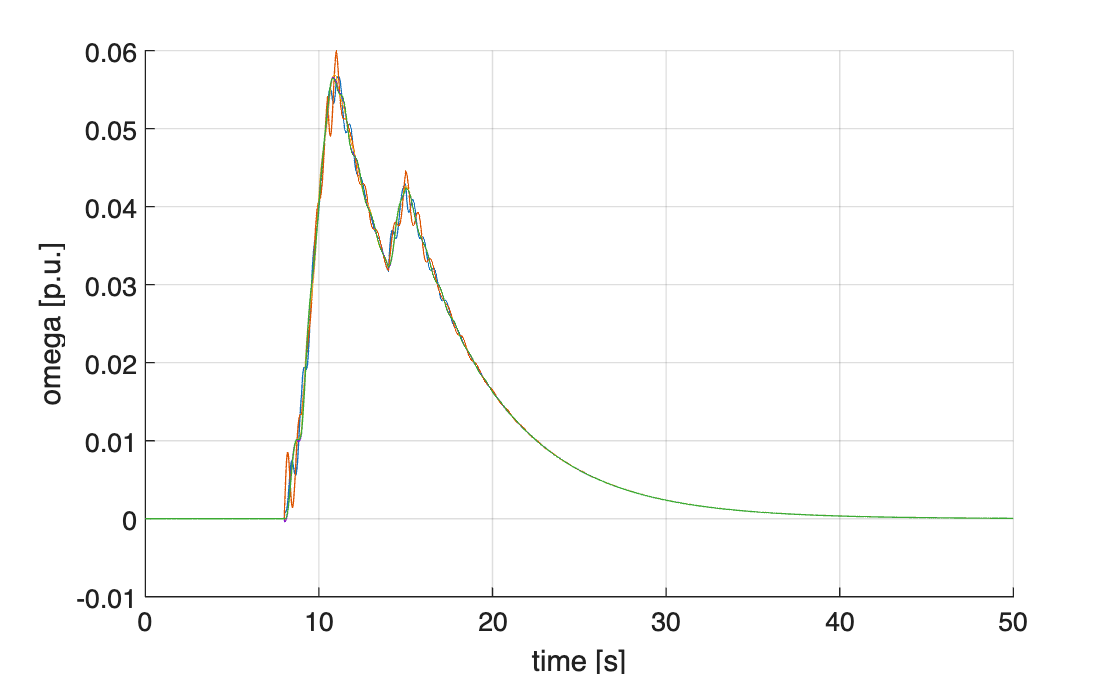


o = cell(5,1);
o{1} = odeEventSet("ev1", net, "TimeSpan",        3, "OffsetState", "delta", "OffsetUnit", "SG1B001", "OffsetValue", pi/6);
o{2} = odeEventSet("ev2", net, "TimeSpan", [ 8,10.5], "InputUnit", "SG1B002", "InputName", ["Pmech";"Vfield"], "InputValue", {0.7; @(t)sqrt(t)*0.1+1});
o{3} = odeEventSet("ev3", net, "TimeSpan", [14,15.0], "InputUnit", "LPQ2B002", "InputName", ["Pload";"Qload"], "InputValue", {@(t) 0.1*t^2-0.2*t+1; @(t) 0.1*sqrt(t)*0.1});
o{4} = odeEventSet("ev4", net, "TimeSpan", [ 8,8.02], "FaultBus", "B008");
o{5} = odeEventSet("ev5", net, "TimeSpan", [ 9,11.0], "TripUnit", "LPQ2B003");

sol = net.simulate([0,50], o{:});

xsol = sol.odeResults;
figure
hold on
arrayfun(@(i) plot(xsol.t, xsol.Bus(i).Component(1).X.omega), [1,2,3,6,8]);

grid on
xlabel("time [s]")
ylabel("omega [p.u.]")

**ちなみに上のグラフは、上記5つのイベントを発生させたときのシミュレーション結果になります。**

# **次に、GFM・GFL最適選択にチャレンジしてみましょう !!**

# 付録:

## １．出力結果のデータ構造

        によって出力されたデータ "out" にはシミュレーションの様々な解析結果が格納されています．

        今回解析を行いたい各発電機の周波数偏差('omega')の時系列データは

        とすることで得られます．

        一方でシミュレーション中のサンプリング時間のデータは以下のようにして取得することが出来ます．

        つまり，例えば以下のように実行することで発電機1の周波数偏差の応答をプロットすることが出来ます！

% function L2 = culculate_l2norm(str)
%     L2 = zeros(1,5);                       %データ格納用の行列を定義
%     fprintf('\n各発電機の周波数偏差のL２ノルム(大きい順) \n\n')
% 
%     c_num = [1,2,3,6,8];
%     %IEEE68busは母線1~16に同期発電機が付加されている．
%     for i = 1:numel(c_num)    
%         t        = str(c_num(i)).t;
%         omega_i  = str(c_num(i)).X{1}.omega;       % 母線iの周波数偏差の応答データを抽出
%         omega2_i = omega_i.^2;              % 応答データの各要素を２乗する
%         integer  = trapz(t, omega2_i);      % ２乗したデータを数値積分する
%         L2_i     = sqrt(integer);           % 積分値の平方根を取りL２ノルムを計算
%         L2(i)    = L2_i;                    % 得られたL2ノルムを配列に格納する
%     end
%     [~, idx_sort] = sort(L2,'descend');     %L2ノルムの大きい順にソートした機器の番号を得る
% 
%     strstr = {'同期発電機','同期発電機','同期調相機','同期調相機','同期調相機'};
%     for i = idx_sort
%         disp([strstr{i},num2str(i,'%.2d'),'のl2ノルム: ',num2str(L2(i))])
%     end
% end
% 
% 